# Sea Ice Floe Image Segmentation 1.0.0

**Author: Alexis Anne Denton    02-14-2022    Last Updated:    03-07-2022**

**Description: This script segments (identifies and labels) individual sea ice floes in an image (such as from a satellite, or aerial platfrom). **

Details: 

This scripted algorithm was written for and used to segment high-resolution optical satellite images in the accompanying submitted manuscript (preprint, in review), Denton and Timmermans (2021) ([https://doi.org/10.5194/tc-2021-368](https://doi.org/10.5194/tc-2021-368)).

This image segmentation algorithm employs "restricted growing" (Soh et al., 1998) techniques to 

- Classify the image to binary (ocean pixels set to 0 [black], ice pixels set to 1 [white]).

- Seperate the classifed ice floes from each other via iterative image erosion.

- Label the seperate, eroded ice floes with a unique numerical value.

- Regrow the labeled ice floes to their original (restricted) size and shape via iterative image expansion.

- Clear image borders of intersecting floes, not to be included in analysis of floe properties (as they are not measured completely).

- Save the resulting image segmentation.

***Steps 1 and 2 require input parameters by the user - Classification threshold and the number of erosions used on the first iteration.*** The rest of the algorithm is automated.

From the final segmentation, floe properties, such as size, shape, and number, may easily be retrieved. See regionprops for further details about retrieving object properties in labeled arrays. 

Please see Denton and Timmermans (2021) for details. 

The code repository containing the most recent release of this algorithm can be found at [https://github.com/dentonaa/sea-ice-floe-segmentation.](https://github.com/dentonaa/sea-ice-floe-segmentation.) 

**This algorithm was developed to contribute an easy, automated, and reproducable method to the Arctic science community for the identification of sea ice floes in remote sensing imagery. If you use this algorithm in your work or research or for any other reason, credit the author here (Alexis Denton) and cite the code DOI issued by Zenodo from the GitHub repository. The DOI badge on GitHub points to the most recent release of the repository. To obtain the DOI, read the Description in the README.md file at **[**https://github.com/dentonaa/sea-ice-floe-segmentation**](https://github.com/dentonaa/sea-ice-floe-segmentation)**.**

**References:**

Denton, A. A. and Timmermans, M.-L.: Characterizing the Sea-Ice Floe Size Distribution in the Canada Basin from High-Resolution Optical Satellite Imagery, The Cryosphere Discuss. [preprint], [https://doi.org/10.5194/tc-2021-368](https://doi.org/10.5194/tc-2021-368), in review, 2021.

## Import and Check Image

### Define Directories:

Define the file path to the image you wish to segment (not including image file name).

clf;

tstart = tic; %time the script run.
imPath = 'D:\USGS GFL\Original Data\'; %set variable imPath to user defined image file path
imName = 'chukchi_20080612_1.tif'; %set variable imName to user defined image file name
baseName = imName(1:end-4); %retrieve base image name without file .ext

Define the file path to the location you wish to save the segmented image files, ensuring to end the path with \ or / (depending on your OS). 

writePath = 'C:\Users\Alexis\OneDrive - Yale University\Documents\MATLAB\GitHub\sea-ice-floe-segmentation\';

### Import Image:

 

cd(imPath)

% Import image
im = imread(imName); 

% Retrieve image metadata
rows = size(im,1);
cols = size(im,2);

% Pad image borders for later border clearing
impad = padarray(im,[1 1],0,'both'); 
clear im %clear im to save memory for large images.

% Retrieve padded image metadata
rowspad = size(impad,1);
colspad = size(impad,2);

### Display Image:

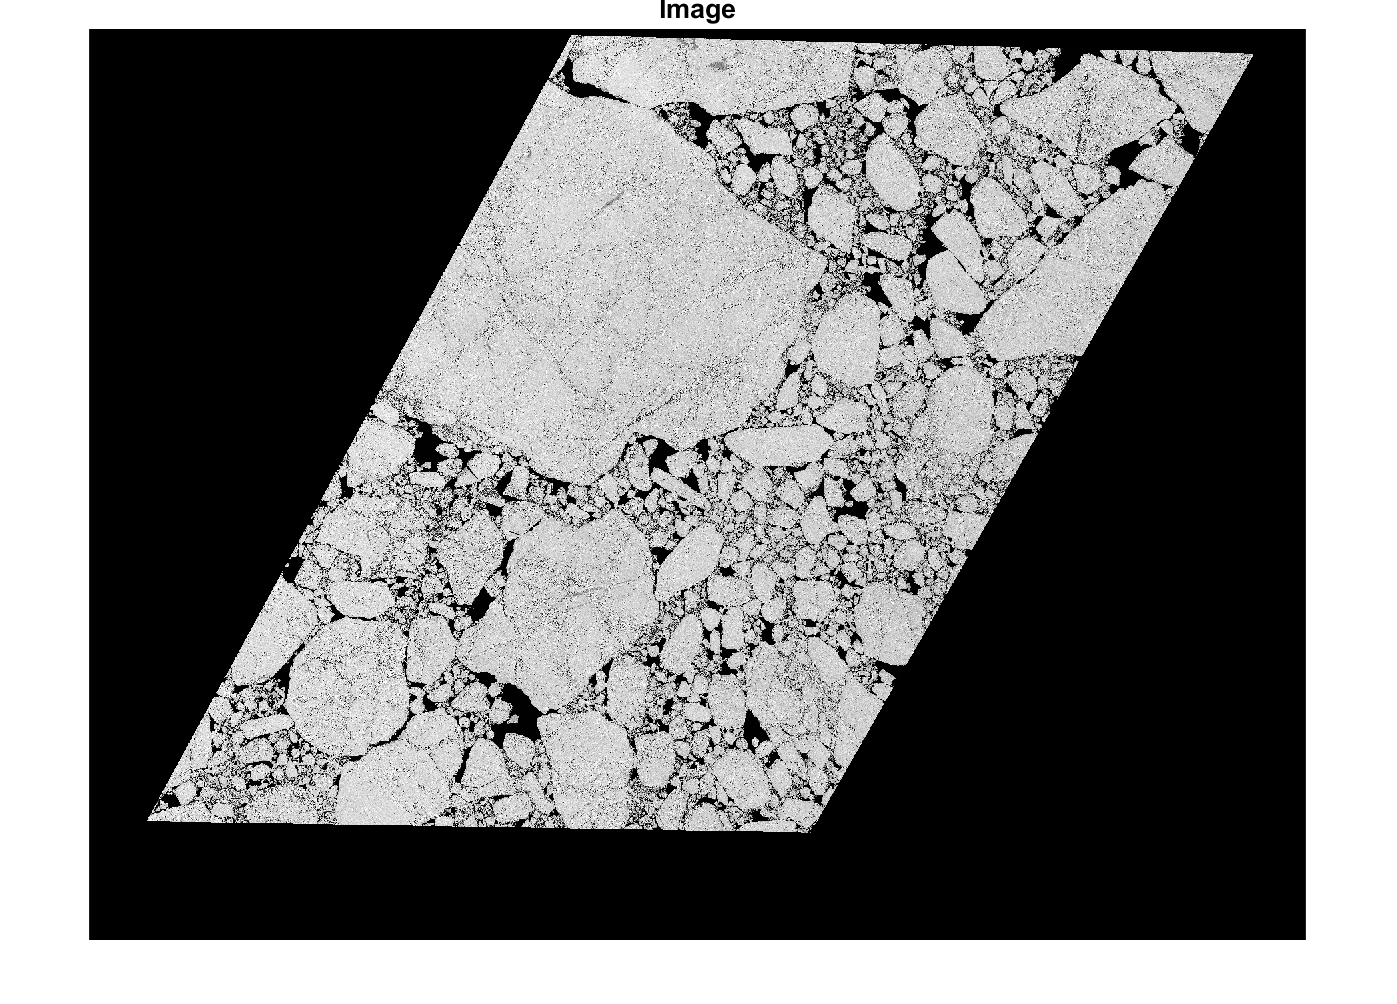

imshow(impad)
title('Image','FontSize',20)

### Check Image:

Check if there are pixel values of 1 outside of image bounds (which can occur with satellite images). This will cause issues with image border clearing later.

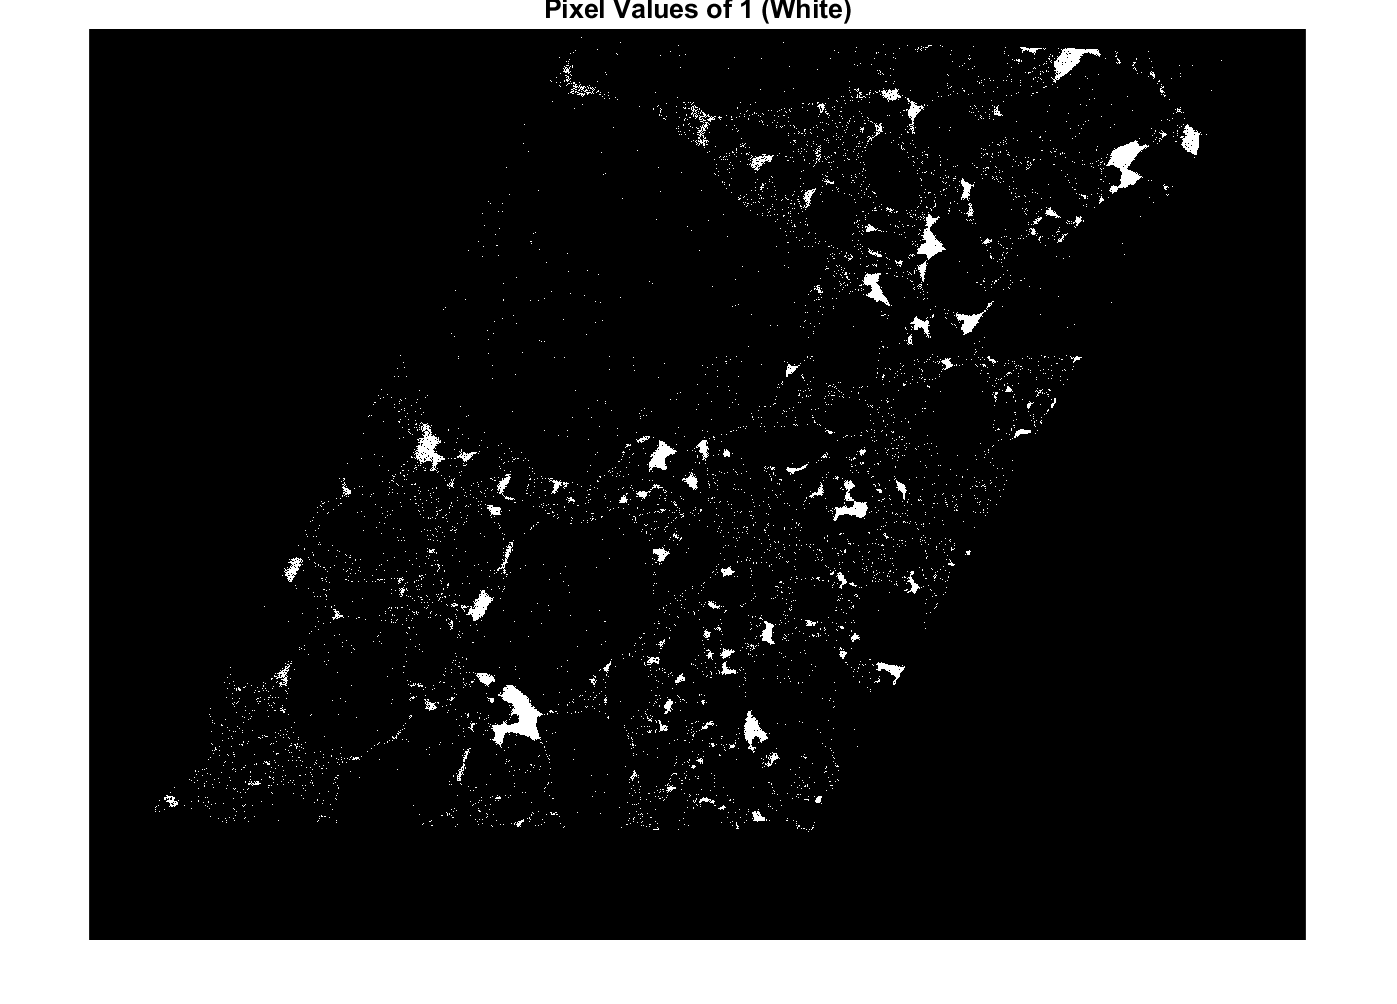

im_1 = impad == 1; %locate pixel values of 1

imshow(im_1)
title('Pixel Values of 1 (White)','FontSize',20)

clear im_1

If pixel values of 1 exist only outside of the image bounds, reset those values to 0. This will prevent border clearing issues.

pixval1out = 0;     
if pixval1out == 1  
    impad(impad==1) = 0;
end

borderInds = ~impad; %retrieve image border (No Data) indices

% Create image border mask
imInds = ~borderInds;
seb = strel('disk',1);
imIndse1 = imerode(imInds,seb);
imIndse2 = imerode(imIndse1,seb);
borderStripInds = logical(imInds-imIndse2);
clear borderInds imInds seb imIndse1 imIndse2

Verify image borders (where No Data Values and Image Data border each other) are correct:

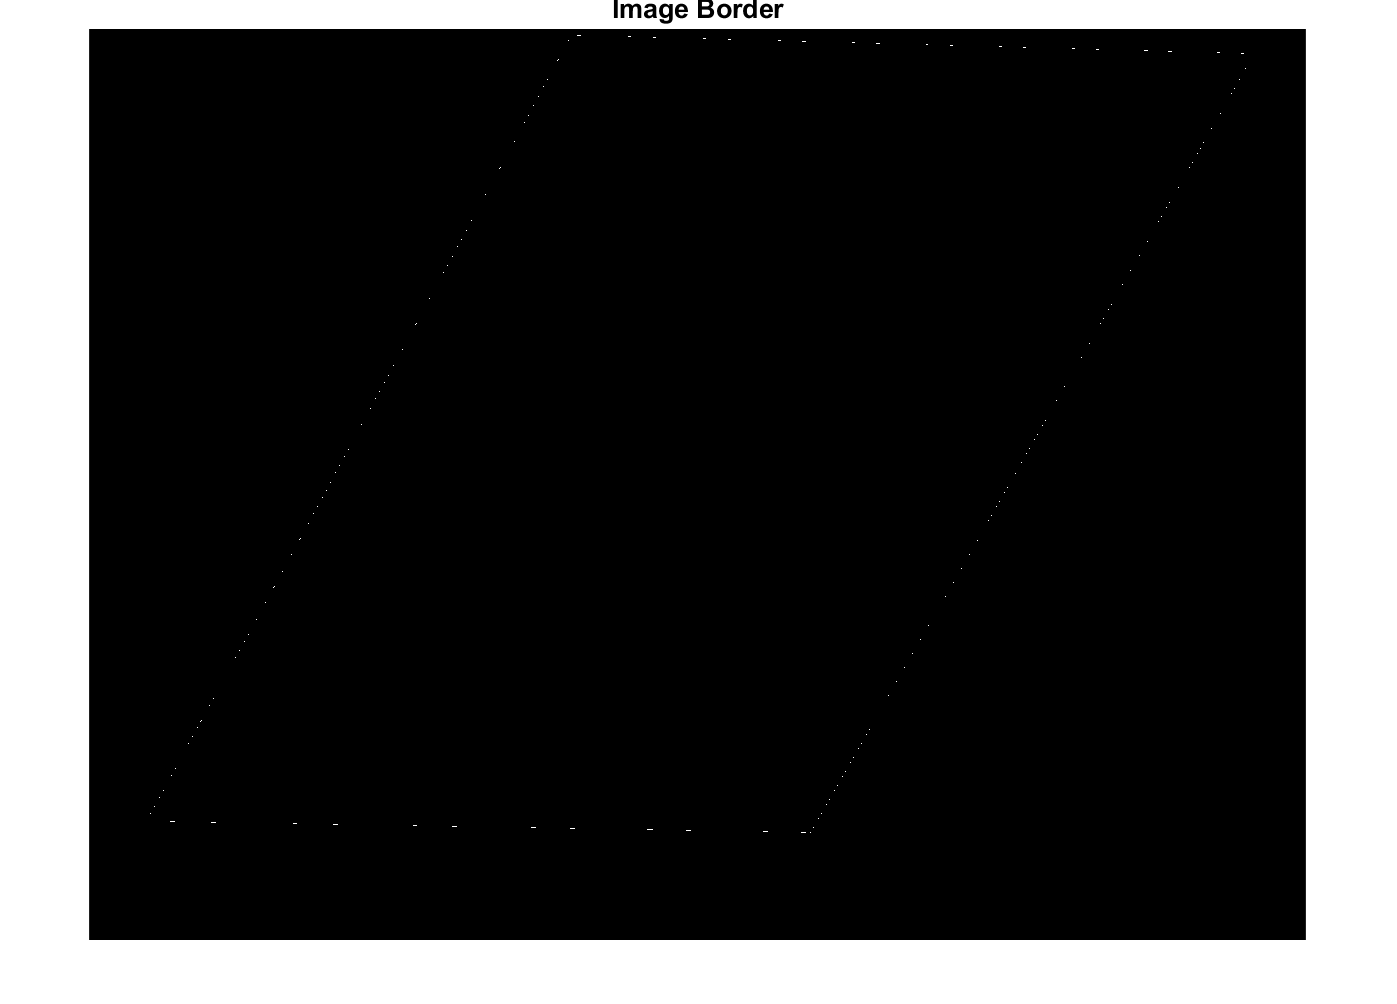

imshow(borderStripInds)
title('Image Border','FontSize',20)

## 1. Classify Image

imGray = mat2gray(impad); %convert image to grayscale (0 to 1) from 0 to 256 values for classification with imbinarize.

### Inspect Image Histogram:

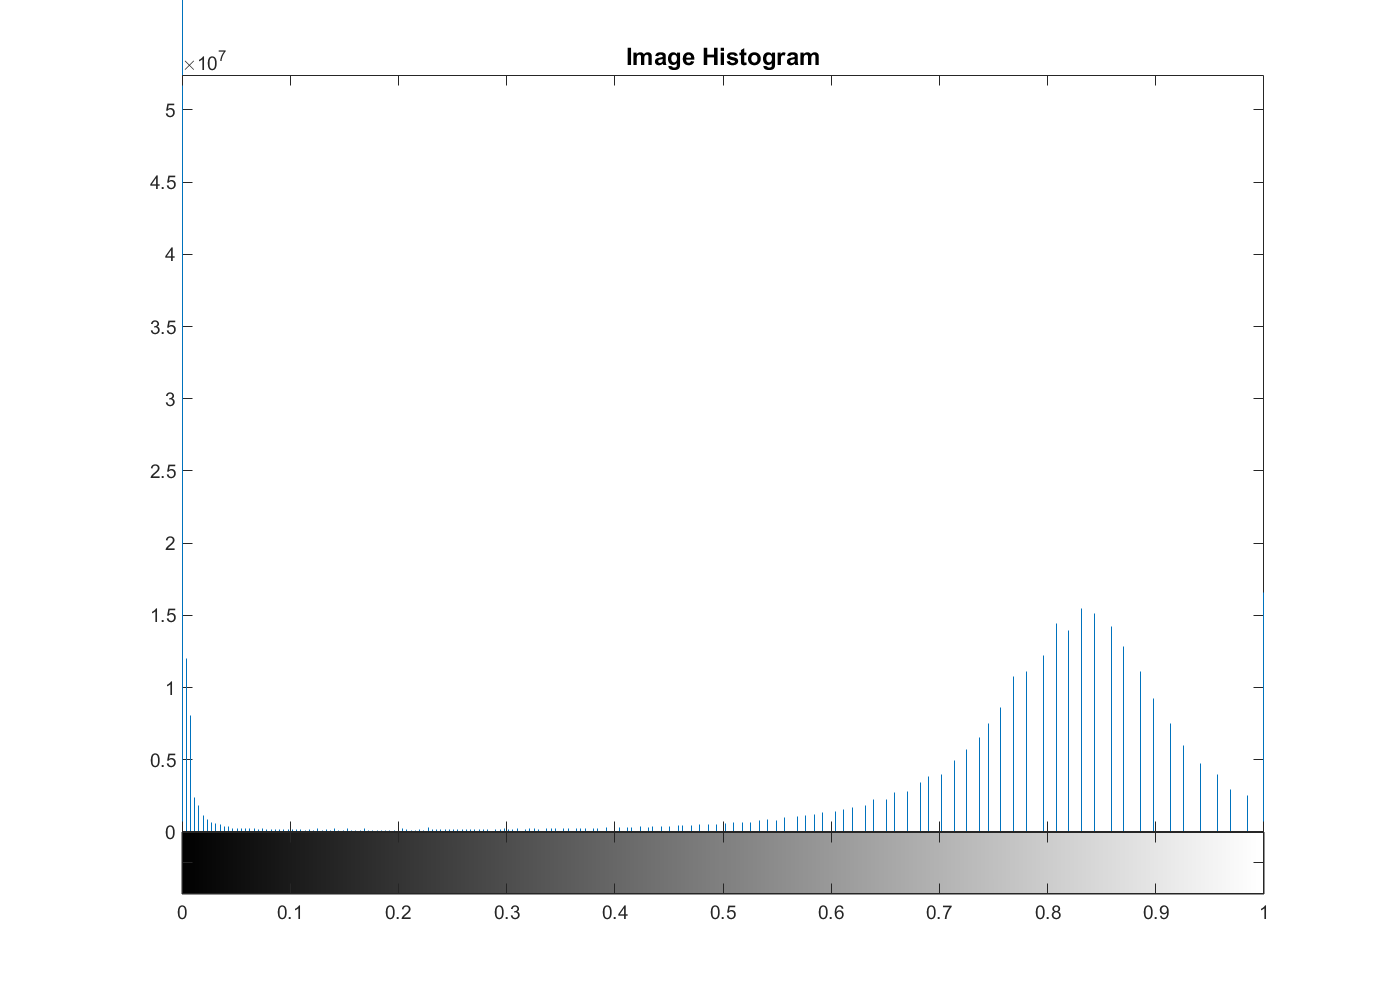

 

imhist(imGray);
h = gca;
h.FontSize = 14;
ha = get(gcf,'children');
set(ha(1),'fontsize',14);
title('Image Histogram','FontSize',18)

### Choose Classification Threshold:

Now choose a Classification Threshold (above which pixels will be set to ice, below which water) from 0 to 1.

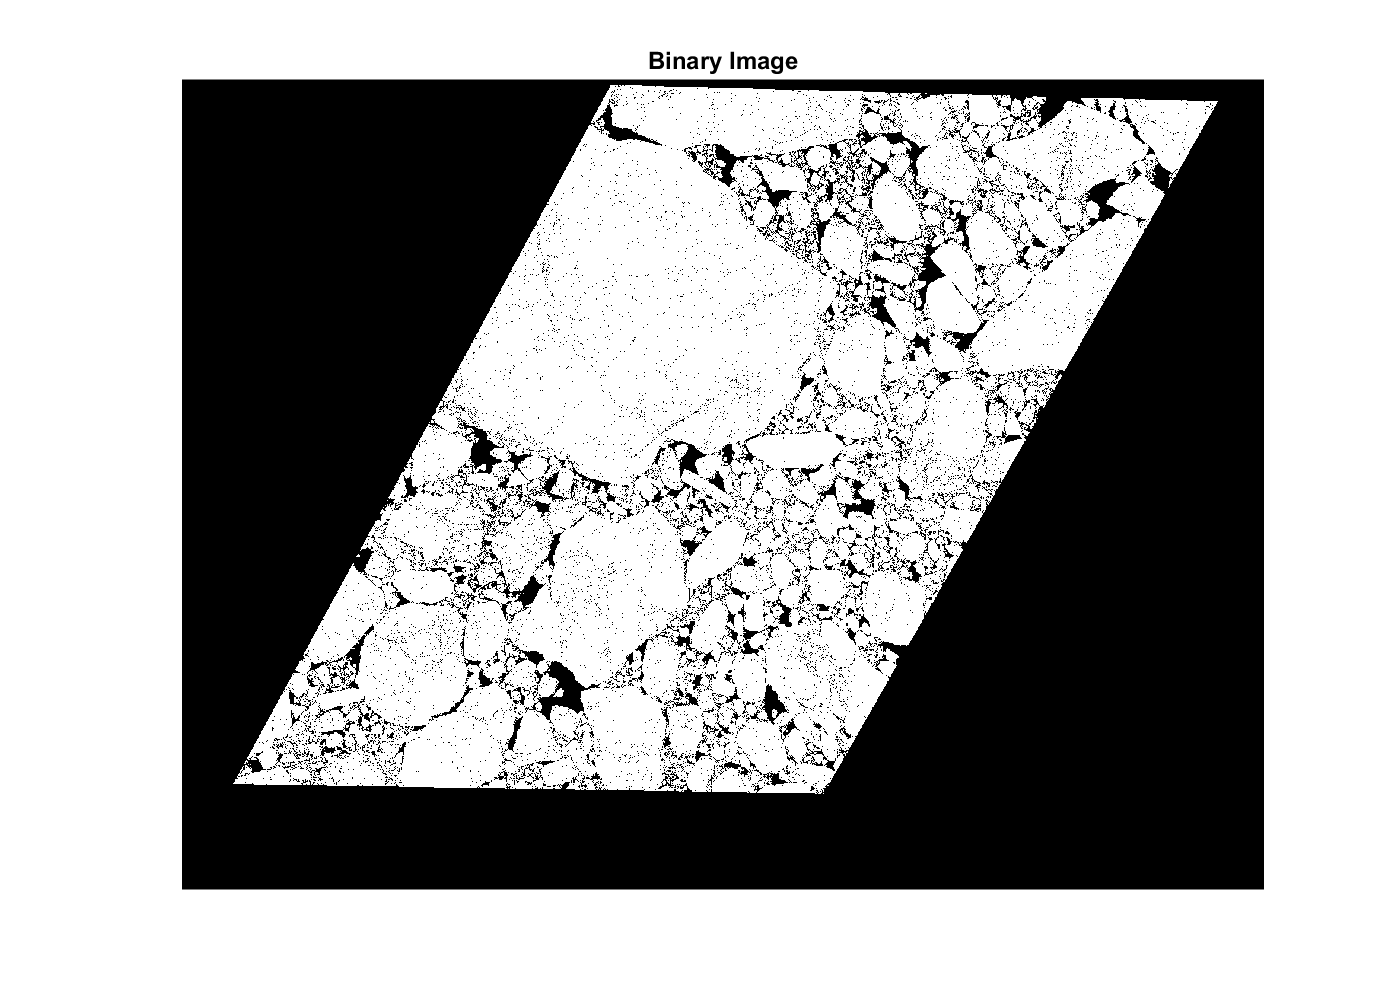

bwt = 0.3;  

bwpad = imbinarize(imGray,bwt); %classify the image using the user chosen classification threshold.

imshow(bwpad)
title('Binary Image','FontSize',18)

### Save Classified Image:

% Save classified image to user defined segmentation file path

Once you are happy with your chosen classification threshold, save the classified image.

 

bw = bwpad(2:end-1,2:end-1);
imwrite(bw, [writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'_classified.png'])
fprintf('Image Saved')

Image Saved

## 2. Erode Image

### Choose Number of Erosions:

Test-Erode the image using your chosen number of erosions to determine if the sea ice floes are sufficiently seperated. 

Note that the number of erosions you choose will be the number of erosions used to seperate the largest floes. Each successive hierarchical segmentation step will use approximately half the number of previous erosions, until the last few steps, with erosion numbers 1 and 0, to seperate the smallest floes. 

maxNumErosions = 2;  

% Check if floes are seperated sufficiently by test-eroding the image.
fprintf('Eroding Image to Test Number of Erosions...\n');

Eroding Image to Test Number of Erosions...


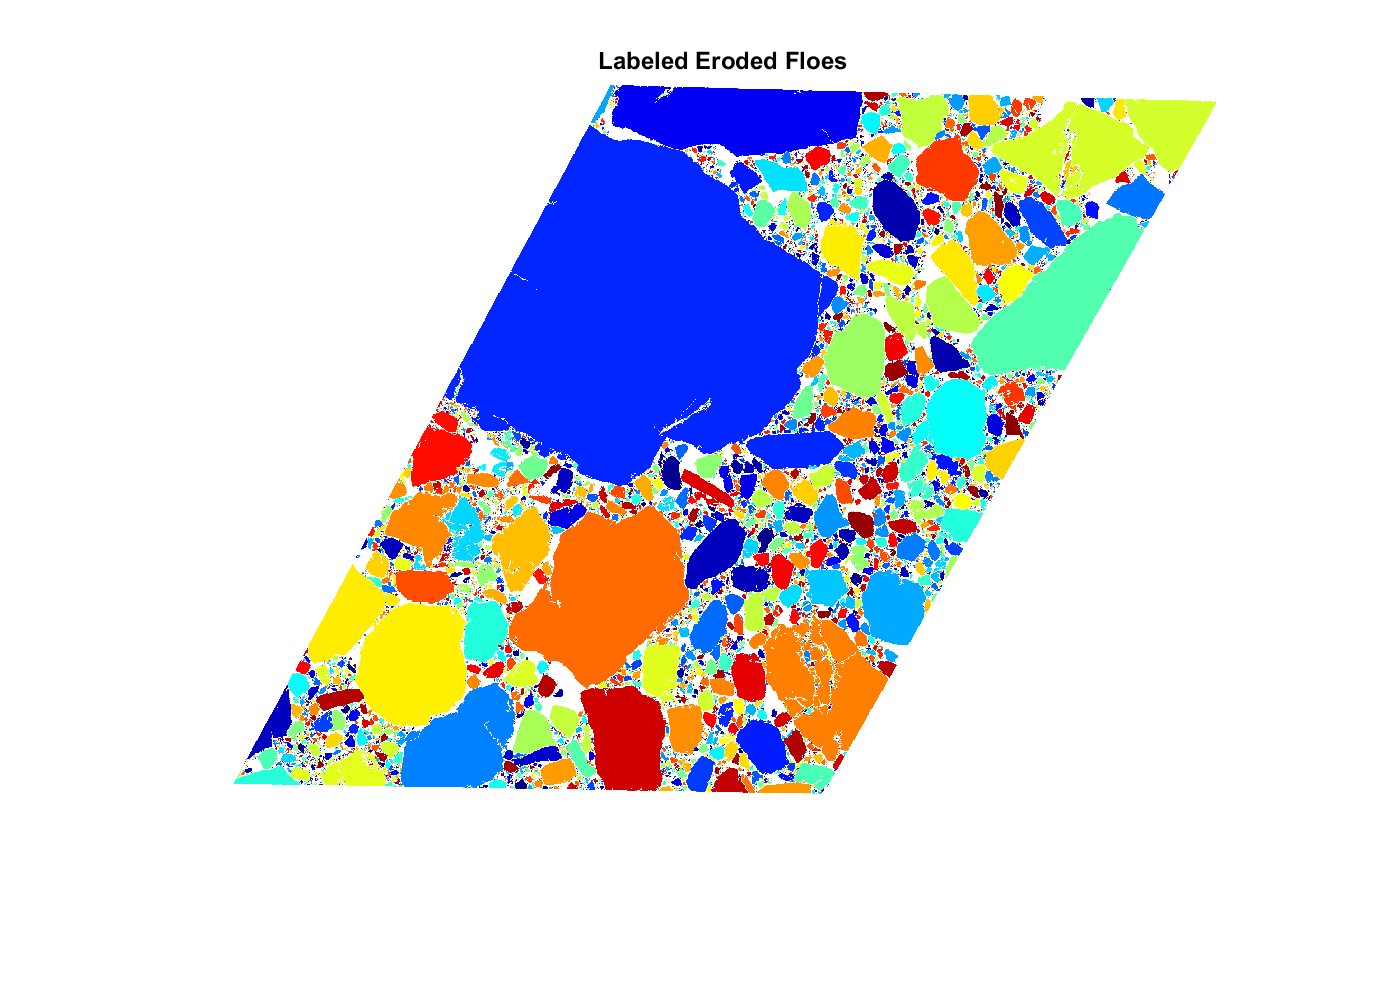

seRadius = 1; %use a round structuring element of radius 1, for use in imerode.
se = strel('disk',seRadius);

% Test-erode image 
bwetest = bwpad;
for i = 1:maxNumErosions
    bwetest1 = bwetest;
    bwetest = imerode(bwetest1,se);
end
clear bwetest1

% Fill Expanded Meltponds/Ocean Holes in Floes 
bwetest = imfill(bwetest,'holes');

% Label Test-Eroded Image
Letest = bwlabel(bwetest);
Letestrgb = label2rgb(Letest,'jet','w','shuffle'); %convert test-eroded numerical label array to rgb image

% Display Test-Eroded, Labeled Image
imshow(Letestrgb)
title('Labeled Eroded Floes','FontSize',18)

clear bwetest Letest Letestrgb;

## 3. Segment Image

#### (Erode-Fill-Label-Expand Largest to Smallest Sea Ice Floes)

Once you are happy with your chosen parameters, Classification Threshold and Number of Erosions, segment the image. 

Hierachical Step 1, Floe Erosion 1
Hierachical Step 1, Floe Erosion 2


Hierachical Step 1, Filling Holes in Floes


Hierachical Step 1, Labeling Floes


Hierachical Step 1, Floe Expansion 1


Elapsed time is 7.992179 seconds.
Elapsed time is 8.648261 seconds.
Elapsed time is 9.150815 seconds.
Elapsed time is 9.978855 seconds.
Elapsed time is 11.273701 seconds.
Elapsed time is 10.215743 seconds.
Elapsed time is 10.276727 seconds.
Elapsed time is 10.315571 seconds.
Elapsed time is 10.272358 seconds.
Elapsed time is 10.495653 seconds.
Elapsed time is 10.394979 seconds.
Elapsed time is 10.295254 seconds.
Elapsed time is 10.462595 seconds.
Elapsed time is 10.529833 seconds.
Elapsed time is 10.506770 seconds.
Elapsed time is 10.569159 seconds.
Elapsed time is 10.594281 seconds.
Elapsed time is 10.565815 seconds.
Elapsed time is 10.582049 seconds.
Elapsed time is 10.594922 seconds.
Elapsed time is 10.646956 seconds.
Elapsed time is 10.679680 seconds.
Elapsed time is 10.851194 seconds.
Elapsed time is 10.826395 seconds.
Elapsed time is 10.825715 seconds.
Elapsed time is 10.925407 seconds.


26 expansion iterations at this step

Hierachical Step 1, Floe Expansion 2


Elapsed time is 11.086138 seconds.
Elapsed time is 11.035620 seconds.
Elapsed time is 11.048880 seconds.
Elapsed time is 11.217561 seconds.
Elapsed time is 11.246510 seconds.
Elapsed time is 11.175615 seconds.
Elapsed time is 11.209702 seconds.
Elapsed time is 11.254795 seconds.
Elapsed time is 11.081397 seconds.
Elapsed time is 11.126264 seconds.
Elapsed time is 12.376839 seconds.
Elapsed time is 11.530712 seconds.
Elapsed time is 11.321142 seconds.
Elapsed time is 11.278289 seconds.
Elapsed time is 11.140057 seconds.
Elapsed time is 11.076063 seconds.
Elapsed time is 11.271575 seconds.
Elapsed time is 11.212464 seconds.
Elapsed time is 11.603526 seconds.
Elapsed time is 11.226726 seconds.
Elapsed time is 11.183058 seconds.
Elapsed time is 11.309378 seconds.
Elapsed time is 11.142436 seconds.
Elapsed time is 11.120622 seconds.
Elapsed time is 11.129292 seconds.
Elapsed time is 11.163049 seconds.
Elapsed time is 11.113340 seconds.
Elapsed time is 11.247189 seconds.
Elapsed time is 11.1

34 expansion iterations at this step

Hierarchical Step 1, Segmenting and Filtering Labeled Floes Only

Hierarchical Step 1, Saving Current Segmented Image

Hierachical Step 2, Floe Erosion 1


Hierachical Step 2, Filling Holes in Floes


Hierachical Step 2, Labeling Floes


Hierachical Step 2, Floe Expansion 1


Elapsed time is 10.927068 seconds.
Elapsed time is 11.252457 seconds.
Elapsed time is 11.200078 seconds.
Elapsed time is 11.073537 seconds.
Elapsed time is 11.024502 seconds.
Elapsed time is 11.019191 seconds.
Elapsed time is 11.108289 seconds.
Elapsed time is 11.388067 seconds.
Elapsed time is 11.225941 seconds.
Elapsed time is 11.256927 seconds.
Elapsed time is 11.018955 seconds.
Elapsed time is 11.289258 seconds.
Elapsed time is 11.097920 seconds.
Elapsed time is 11.000242 seconds.
Elapsed time is 11.072747 seconds.
Elapsed time is 11.376365 seconds.
Elapsed time is 10.985605 seconds.
Elapsed time is 11.040145 seconds.
Elapsed time is 10.992885 seconds.
Elapsed time is 10.973500 seconds.
Elapsed time is 11.030597 seconds.
Elapsed time is 10.973638 seconds.
Elapsed time is 11.032175 seconds.
Elapsed time is 12.200590 seconds.
Elapsed time is 12.277503 seconds.
Elapsed time is 11.201689 seconds.
Elapsed time is 10.936546 seconds.
Elapsed time is 11.060014 seconds.
Elapsed time is 10.9

34 expansion iterations at this step

Hierarchical Step 2, Segmenting and Filtering Labeled Floes Only

Hierarchical Step 2, Saving Current Segmented Image

Final Hierarchical Step, No Erosions

Final Hierarchical Step, Segmenting and Filtering Final Labeled Floes

Saving Final Segmented Image

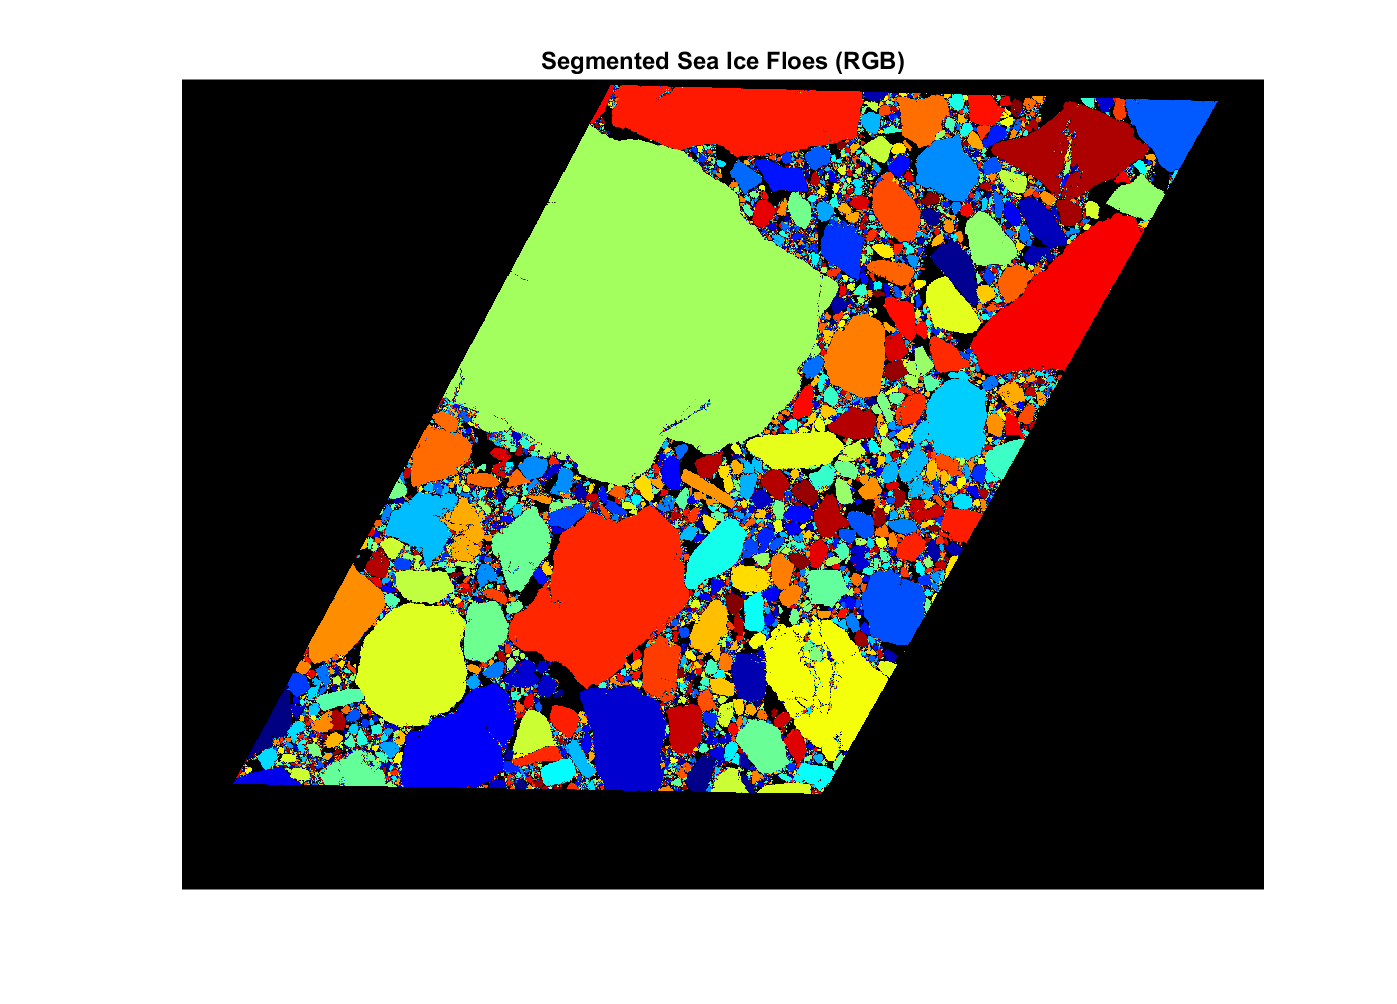

 

% Create an erosion vector, numErosions, containing every subsequential erosion number.
% WARNING: numErosions changes size each iteration of the while loop, but this is ok while the array is small. 
% Memory is not preallocated to numErosions because we do not know its size beforehand with the choice of any maxNumErosions. 
% numErosions is created to remove the necessity of a while loop during hierarchical segmentation.
m = maxNumErosions;
i = 0;
numErosions = double.empty;
while m >= 1
    i = i + 1;
    if m == 1
       numErosions(i) = 1;
       numErosions(i+1) = 0;
       break
    end
    numErosions(i) = m;
    m = floor(m/2); %use a half-step hierarchical scheme in which each successive erosion-expansion iteration (Stern et al., 2018)
    % uses half the number of erosion iterations to seperate and segment successive groups of smaller ice floes. 
    % Another possible scheme would be a square-root step,for example.
end
clear m

% Initialize Final Arrays
numf = 0; %initialize the final floe labels, numf, to start at value 0. 
L = zeros([rowspad colspad]); %initialize the final regrown label matrix, L, as an empty array.
bwfilt = bwpad; %initialize final bw filtered image (which will contain no floes at the end of the segmentation).

for i = 1:length(numErosions)   %begin heirarchical segmentation loop which runs as long as there are floes left in the filtered binary image to segment.
% SEGMENTATION LOOP STARTS----------------------------------------------------------------------------------------------------------------------------------------------
% Initialize Erosion Arrays
    bwe = bwfilt; 
    erosionTag = zeros([rowspad colspad]);
% (Erosion-Expansion on Initial Runs)
% EROSION-EXPANSION LOOP STARTS-----------------------------------------------------------------------------------------------------------------------------------------
    if numErosions(i) >= 1               
% Erode Image
% EROSION LOOP STARTS---------------------------------------------------------------------------------------------------------------------------------------------------
        for n = 1:numErosions(i)
            formatSpec = 'Hierachical Step %g, Floe Erosion %g\n';
            fprintf(formatSpec,i,n)
            
            bwe1 = bwe;
            bwe = imerode(bwe1,se);
            erosionTag(logical(bwe1-bwe)) = n; %tag eroded pixels
        end
        clear bwe1
% EROSION LOOP ENDS-----------------------------------------------------------------------------------------------------------------------------------------------------

% Fill Expanded Meltponds/Ocean Holes in Floes 
        formatSpec = 'Hierachical Step %g, Filling Holes in Floes\n';
        fprintf(formatSpec,i)

        bwe = imfill(bwe,'holes');        

% 3. Label Sea Ice Floes
% Label Eroded Image
        formatSpec = 'Hierachical Step %g, Labeling Floes\n';
        fprintf(formatSpec,i)
        
        [Le,nume] = bwlabel(bwe);
%         Lergb = label2rgb(Le,'jet','w','shuffle'); 
        
%         imshow(Lergb)   
%         snapnow;
%         title('Labeled Eroded Floes','FontSize',18)
%         clear Lergb;

% 4. Expand Sea Ice Floes
% Initialize Expansion Arrays
        Lr = Le; %initalize regrowing label array to eroded label array
        clear Le;
        
        bwr = zeros([rowspad colspad]); %initialize expansion binary image
        expansionTag = bwe;
        clear bwe
        
% Expand (Regrow) Image
% EXPANSION LOOP STARTS--------------------------------------------------------------------------------------------------------------------------------------------------------
        for n = 1:numErosions(i)
            tExpandStart = tic;
            formatSpec = 'Hierachical Step %g, Floe Expansion %g\n';
            fprintf(formatSpec,i,n)
            
            Lr(~Lr) = NaN;    
            erosionStep = -n+numErosions(i)+1;
            Lr(erosionTag==erosionStep) = NaN;  
            regrowing = true;
            expit = 0;  
            
            while regrowing == true
                expit = expit + 1;                
                nanI = isnan(Lr);                
                tic
                LrMode = modefilt(Lr);
                toc
                Lr(erosionTag==erosionStep) = LrMode(erosionTag==erosionStep);
                nanF = isnan(Lr);        
                nanDiff = abs(nanI-nanF);
                regrowing = any(nanDiff,'all');        
            end
            
            formatSpec = '%g expansion iterations at this step';
            fprintf(formatSpec,expit)
            tExpandEnd = toc(tExpandStart);              
            bwr(~isnan(Lr)) = 1;            
            expansionTag = expansionTag + (erosionTag==erosionStep);
            expansionTag(expansionTag>0) = 1;    
            
% Flag regrown unlabelled floes    
            unlabeledFloes = expansionTag - bwr;             
            [Lu,numu] = bwlabel(unlabeledFloes);
            Lu(Lu>0) = nume + 1;           
            Lr(isnan(Lr)) = 0;
            Lr = Lr + Lu;  
        end    
        clear LrMode expansionTag erosionTag Lu nanI nanF nanDiff bwr unlabeledFloes;
% EXPANSION LOOP ENDS-----------------------------------------------------------------------------------------------------------------------------------------------------------
        
%         Lrrgb = label2rgb(Lr,'jet','w','shuffle'); %convert numerical regrown label array to rgb        

%         imshow(Lrrgb)  
%         title('Labeled Regrown Floes','FontSize',18)
%         snapnow;
%         clear Lrrgb;
        
% Skip Erosion-Expansion on Final Step
    else
        fprintf('Final Hierarchical Step, No Erosions')
        [Le,nume] = bwlabel(bwfilt); %skip erosion-expansion on final hierarchy run for the smallest floes.
        Lr = Le;
        clear bwe erosionTag Le
    end
% EROSION-EXPANSION LOOP ENDS--------------------------------------------------------------------------------------------------------------------------------------------

% Segment Labelled Floes Only
% filter the binary image of already-segmented floes for the next hierarchical iteration and ddd only the labeled and regrown floes (Lregrown) into a new label matrix.
    if i == length(numErosions)
        fprintf('Final Hierarchical Step, Segmenting and Filtering Final Labeled Floes')
    else 
        formatSpec = 'Hierarchical Step %g, Segmenting and Filtering Labeled Floes Only';
        fprintf(formatSpec,i);
    end

    bwfilt(Lr<=nume) = 0; %filter binary image of segmented floes
    
%     imshow(bwfilt)
%     title('Filtered Binary Image','FontSize',18)

% Relabel floes and initialize Lbc for border clearing
    Lr(Lr>nume) = 0;
    Lr(Lr>0) = Lr(Lr>0) + numf; 
    L = L + Lr;
    
% Save unpadded labeled and filtered binary images at this step         
    if i == length(numErosions)
        fprintf('Saving Final Segmented Image');
    else
        formatSpec = 'Hierarchical Step %g, Saving Current Segmented Image';
        fprintf(formatSpec,i);
    end
    
    Lrgb = label2rgb(L(2:end-1,2:end-1),'jet','k','shuffle');
    wLrgb = whos('Lrgb');
    
    imshow(Lrgb)
    title('Segmented Sea Ice Floes (RGB)','FontSize',18)
    
    % Pause L to save unpadded L as "L" and retrieve padded L immediately after
    Lpause = L;
    L = L(2:end-1,2:end-1);
    numfmax = max(Lpause,[],'all');
    save([[writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'e',num2str(maxNumErosions),'hs'],'_labeled.mat'],'rows','cols','bwt','bw','numErosions','L','Lrgb','numfmax','-v7.3')
    L = Lpause;
    clear Lpause
    
    if wLrgb.bytes < 2^32-1
        imwrite(Lrgb,[[writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'e',num2str(maxNumErosions),'hs'],'_labeled_rgb.png']);
    else
        imwrite(Lrgb(1:floor((end)/2),1:end,:),[[writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'e',num2str(maxNumErosions),'hs'],'_labeled_rgb_1.png']);
        imwrite(Lrgb(floor((end)/2)+1:end-1,1:end,:),[[writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'e',num2str(maxNumErosions),'hs'],'_labeled_rgb_2.png']);
    end
    
% Ensure Floe Label Chronology
    numf = max(L,[],'all');
end

clear Lr
% SEGMENTATION LOOP ENDS-----------------------------------------------------------------------------------------------------------------------------------------------------

% Check all floes have been labeled
bwfiltAny = any(bwfilt,'all'); %if all floes have been labeled, bwAny == 0.

% Pause L to save it before border-clearing.
Lbc = L;

## 4. Clear Border-Intersecting Sea Ice Floes

 

fprintf('Clearing Border Floes')

Clearing Border Floes

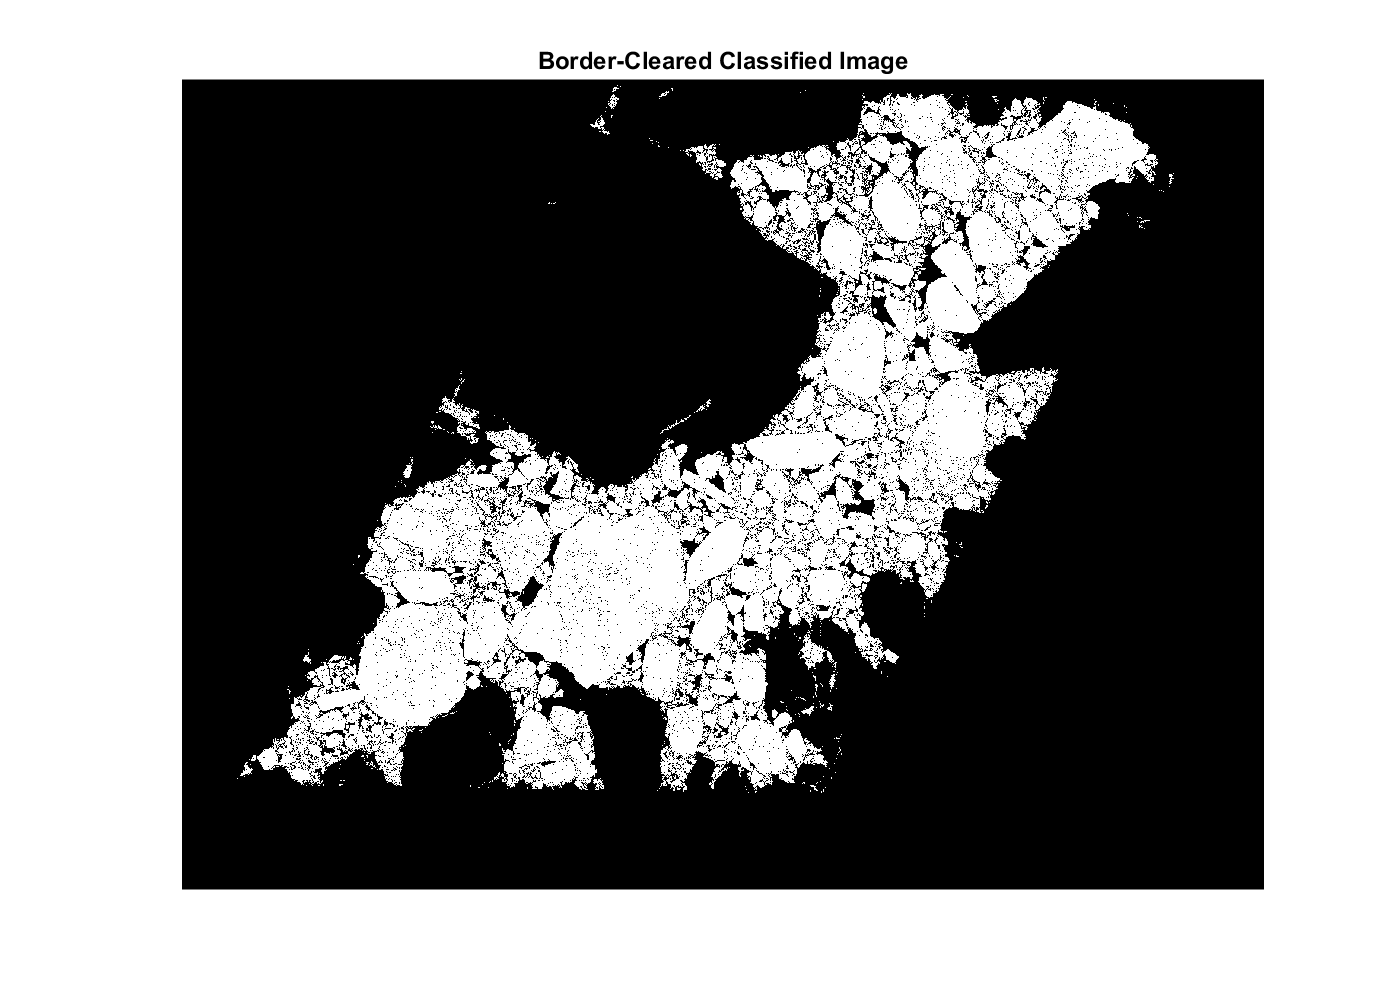

% Initialize final border-cleared L to paused non-border cleared L to allow this section of code to be rerun by user.
L = Lbc;

numfmax = max(L,[],'all'); %retrieve highest numerical floe label (total number of floes segmented).

% Clear label image border floes
borderFloeVals = L(borderStripInds);
borderFloeInds = ismember(L,borderFloeVals);
L(borderFloeInds) = 0;

% Create border-cleared classified image
bwbc = bwpad;
bwbc(borderFloeInds) = 0;
bwbc = bwbc(2:end-1,2:end-1);

imshow(bwbc)
title('Border-Cleared Classified Image','FontSize',18)

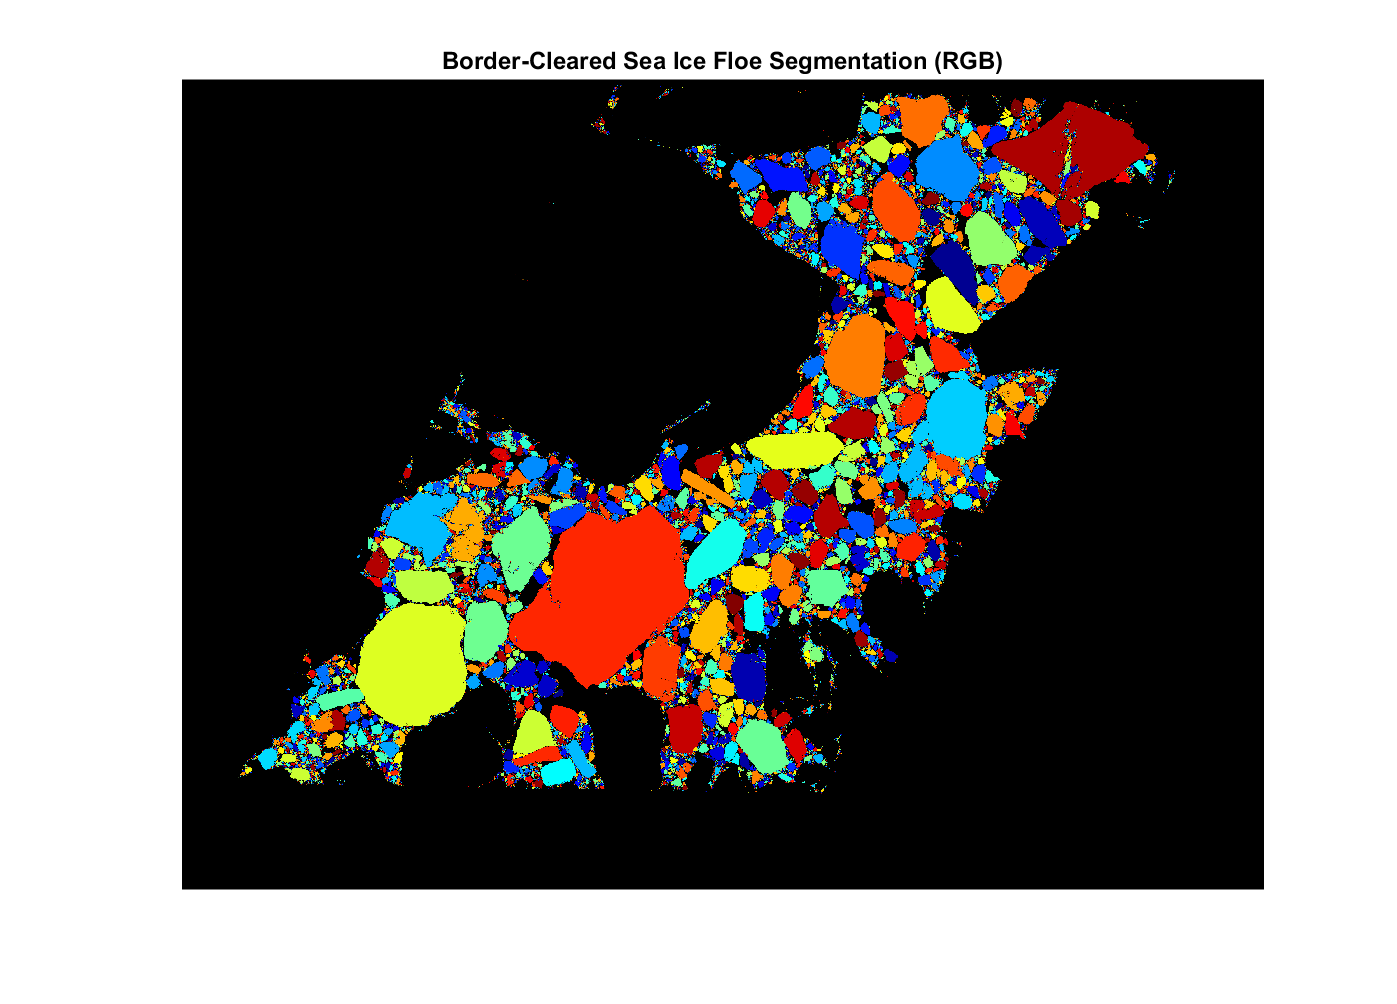


L = L(2:end-1,2:end-1); %unpad border-cleared label image

numfmaxbc = max(L,[],'all'); %retrieve highest border-cleared floe label

Lbcrgb = label2rgb(L,'jet','k','shuffle'); %convert numerical border-cleared label array to RGB image
wLbcrgb = whos('Lbcrgb');

imshow(Lbcrgb)
title('Border-Cleared Sea Ice Floe Segmentation (RGB)','FontSize',18)

## 5. Final Steps and Save Sea Ice Floe Segmented Image

 

save([[writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'e',num2str(maxNumErosions),'hs'],'_bc_labeled.mat'],'rows','cols','bwt','bw','numErosions','L','Lbcrgb','numfmaxbc','-v7.3') %save border-cleared label image

if wLbcrgb.bytes < 2^32-1
    imwrite(Lbcrgb,[[writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'e',num2str(maxNumErosions),'hs'],'_bc_labeled_rgb.png']);
else
    imwrite(Lbcrgb(1:floor(end/2),1:end,:),[[writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'e',num2str(maxNumErosions),'hs'],'_bc_labeled_rgb_1.png']);
    imwrite(Lbcrgb(floor(end/2)+1:end,1:end,:),[[writePath,baseName,'_bwt',strrep(num2str(bwt),'.',''),'e',num2str(maxNumErosions),'hs'],'_bc_labeled_rgb_2.png']);
end
fprintf('Image Segmentation Files Saved; please see accompanying readMe file for a detailed explanation of the Segmentation Files.')

Image Segmentation Files Saved; please see accompanying readMe file for a detailed explanation of the Segmentation Files.

tEnd = toc(tstart); %time the algorithm